[fileName, filePath] = uigetfile({'*.mp3;*.wav', 'Audio Files (*.mp3, *.wav)'}, 'SELECT קובץ אודיו');
if isequal(fileName, 0)
    disp('לא נבחר קובץ.');
    return;
end

% קריאת הקובץ לאודיו
[audioData, sampleRate] = audioread(fullfile(filePath, fileName));

% אם האודיו הוא סטריאו, נבחר את הערוץ הראשון
if size(audioData, 2) > 1
    audioData = audioData(:, 1); % בחר את הערוץ הראשון (שמאלי)
end

% שלב 2: המרת קובץ אם אינו בפורמט WAV
if strcmpi(fileName(end-2:end), 'mp3')
    % המרת קובץ MP3 ל-WAV
    outputFileName = fullfile(filePath, 'audio.wav');
    audiowrite(outputFileName, audioData, sampleRate);
    disp('המרה ל-WAV בוצעה.');
else
    disp('הקובץ כבר בפורמט WAV.');
end

המרה ל-WAV בוצעה.


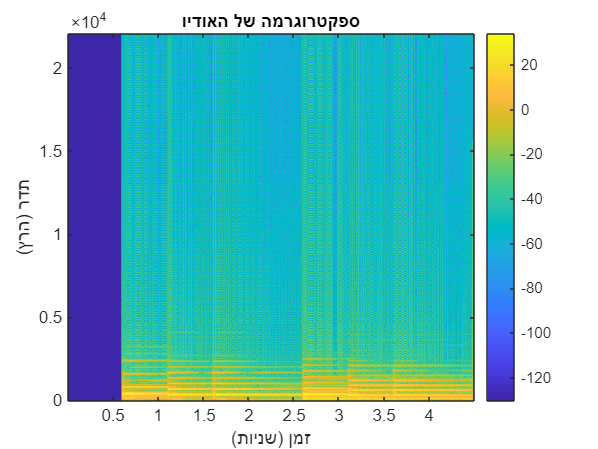


% שלב 3: קריאת הספקטרוגרמה של האודיו
window = 1024; % גודל החלון
overlap = 512; % חפיפות
nfft = 2048; % מספר חישובי ה-FFT
[S, F, T] = spectrogram(audioData, window, overlap, nfft, sampleRate); % הוספנו את F (תדרים) ו-T (זמן)

% הצגת הספקטרוגרמה
figure;
imagesc(T, F, 20*log10(abs(S))); % הצגת הספקטרוגרמה עם עוצמת אות ב-decibels
axis xy;
colorbar;
xlabel('זמן (שניות)');
ylabel('תדר (הרץ)');
title('ספקטרוגרמה של האודיו');

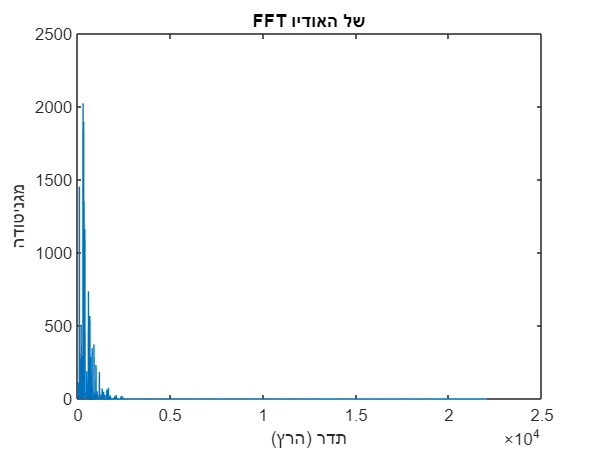


% הצגת FFT של האודיו
figure;
n = length(audioData);
fft_data = fft(audioData);
frequencies = (0:n-1)*(sampleRate/n); % תדרים
magnitude = abs(fft_data); % מגניטודה של ה-FFT
plot(frequencies(1:n/2), magnitude(1:n/2)); % הצגת מחצית ראשונה של ה-FFT
xlabel('תדר (הרץ)');
ylabel('מגניטודה');
title('FFT של האודיו');

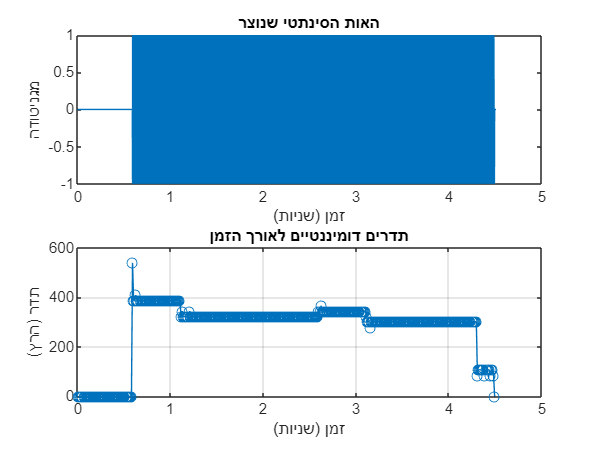


% הצגת נתונים נוספים
%disp('נתונים על הספקטרוגרמה:');
%disp(['תדרים: ', num2str(F(1:10))]); % הצגת התדרים הראשונים
%disp(['זמנים: ', num2str(T(1:10))]); % הצגת הזמנים הראשונים
%saveas(gcf, 'spectrogram.png'); % שומר את הצילום של הספקטרוגרמה
%saveas(gcf, 'fft_plot.png'); % שומר את הצילום של ה-FFT

% חישוב התדרים הדומיננטיים
[~, maxIndex] = max(abs(S)); % מציאת המגניטודה המקסימלית
dominantFrequencies = F(maxIndex); % התדרים הדומיננטיים
synthesizedAudio = zeros(size(audioData)); % אתחול האות
dt = 1 / sampleRate; % מרווח דגימה

for k = 1:length(T)-1
    % זמן למקטע
    t = T(k):dt:T(k+1)-dt;
    
    % יצירת גל סינוסי בתדר הדומיננטי
    freq = dominantFrequencies(k); % התדר הדומיננטי במקטע
    synthesizedAudio(round(T(k)*sampleRate):round(T(k+1)*sampleRate)-1) = ...
        sin(2 * pi * freq * t);
end

% הצגת הגל הסינתטי עם תדרים דומיננטיים
figure;

% גרף של האות הסינתטי
subplot(2, 1, 1);
plot(linspace(0, length(synthesizedAudio)/sampleRate, length(synthesizedAudio)), synthesizedAudio);
title('האות הסינתטי שנוצר');
xlabel('זמן (שניות)');
ylabel('מגניטודה');

% גרף של תדרים דומיננטיים לאורך הזמן
subplot(2, 1, 2);
plot(T, dominantFrequencies, '-o');
title('תדרים דומיננטיים לאורך הזמן');
xlabel('זמן (שניות)');
ylabel('תדר (הרץ)');
grid on;


% יצירת מילון מתאים בין תדרים לתווים
note_frequencies = [261.63, 277.18, 293.66, 311.13, 329.63, 349.23, 369.99, 392.00, 415.30, 440.00, ...
                    466.16, 493.88, 523.25, 554.37, 587.33, 622.25, 659.25, 698.46, 739.99, ...
                    783.99, 830.61, 880.00, 932.33, 987.77, 1046.50, 1108.73, 1174.66, ...
                    1244.51, 1318.51];

notes_names = {'C', 'C#', 'D', 'D#', 'E', 'F', 'F#', 'G', 'G#', 'A', 'A#', 'B', 'C5', 'C#5', 'D5', ...
               'D#5', 'E5', 'F5', 'F#5', 'G5', 'G#5', 'A5', 'A#5', 'B5', 'C6', 'C#6', 'D6', ...
               'D#6', 'E6'};

note_dict = containers.Map(note_frequencies, notes_names);  % יצירת מילון של תדרים לתווים

magnitude_threshold = 0.01;  % רף מינימלי לעוצמת האות

% זיהוי תווים בהתבסס על התדרים והעוצמות
detected_notes = cell(size(dominantFrequencies));
for i = 1:length(dominantFrequencies)
    if max(abs(S(:, i))) > magnitude_threshold  % אם המגניטודה גבוהה מספיק
        [~, index] = min(abs(note_frequencies - dominantFrequencies(i)));  % מצא את התדר הקרוב ביותר
        detected_notes{i} = note_dict(note_frequencies(index));  % שמור את התו
    end
end

% הצגת התו והתדר לכל תו שהוזהה
disp('זיהוי תווים:');

זיהוי תווים:


for i = 1:length(detected_notes)
    if ~isempty(detected_notes{i})
        disp(['זמן: ', num2str(T(i)), ' שניות, תו: ', detected_notes{i}, ', תדר: ', num2str(dominantFrequencies(i)), ' הרץ']);
    end
end

זמן: 0.60372 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.61533 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.62694 שניות, תו: G#, תדר: 409.1309 הרץ
זמן: 0.63855 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.65016 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.66177 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.67338 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.68499 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.6966 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.70821 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.71982 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.73143 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.74304 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.75465 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.76626 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.77787 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.78948 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.80109 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.8127 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.82431 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.83592 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.84753 שניות, תו: G, תדר: 387.5977 הרץ
זמן: 0.8591


% דחיסת התווים לפי שינוי ומעקב אחר משך הזמן
compressed_notes = {};  % רשימה חדשה לתווים ולמשך הזמן שלהם
durations = [];  % רשימת משכים
current_note = detected_notes{1};  % התו הראשון
count = 1;  % מונה משך התו הנוכחי

for i = 2:length(detected_notes)
    if strcmp(detected_notes{i}, current_note)  % אם התו זהה לקודם, הגדל את המונה
        count = count + 1;
    else  % אם התו שונה, שמור את התו והמשך
        compressed_notes{end+1} = current_note;
        durations(end+1) = count;  % משך התו
        current_note = detected_notes{i};  % עדכון התו הנוכחי
        count = 1;  % אתחול מונה למשך התו החדש
    end
end

% הוסף את התו האחרון לרשימה
compressed_notes{end+1} = current_note;
durations(end+1) = count;

% הצגת תהליך דחיסת התווים ומעקב אחר משך הזמן
disp('תהליך דחיסת התווים:');

תהליך דחיסת התווים:


for i = 1:length(compressed_notes)
    disp(['תו: ', compressed_notes{i}, ', משך: ', num2str(durations(i)), ' חלונות']);
end

תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות



% שלב 1: איחוד תווים חוזרים ומפוצלים
min_duration = 0.1;  % סף זמן מינימלי לתו (מינימום של 50ms)
current_note = compressed_notes{1};
current_duration = 0;

i = 1;
while i < length(compressed_notes)
    duration_in_seconds = durations(i) * (window - overlap) / sampleRate;  % חישוב הזמן של התו
    if duration_in_seconds < min_duration  % אם הזמן קטן מהסף
        % אם יש תו זהה מיד לאחריו, נחשב את סך משך הזמן ונאחד
        if i < length(compressed_notes) && strcmp(compressed_notes{i}, compressed_notes{i+1})
            durations(i+1) = durations(i+1) + durations(i);  % איחוד משך הזמן
            compressed_notes(i) = [];  % מחיקת התו המשוכפל
            durations(i) = [];
            continue;  % חזרה להתחלה של הלולאה
        end
    end
    i = i + 1;
end

% הצגת התוצאה הסופית לאחר האיחוד
disp('תוצאה סופית לאחר איחוד תווים:');

תוצאה סופית לאחר איחוד תווים:


for i = 1:length(compressed_notes)
    disp(['תו: ', compressed_notes{i}, ', משך: ', num2str(durations(i)), ' חלונות']);
end

תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות
תו: , משך: 1 חלונות



% שלב 8: סיווג התווים לפי המשך שלהם
% טבלת השוואה למשכי התווים
note_durations = [4.00, 3.00, 2.00, 1.50, 1.00, 0.50, 0.25];
note_types = {'תו שלם (𝅝)', 'תו חצי עם נקודה (𝅗𝅥.)', 'תו חצי (𝅗𝅥)', 'תו רבע עם נקודה (♩.)', 'תו רבע (♩)', 'תו שמינית (♪)', 'תו שש-עשרית (♫)'};

duration_classification = {}; % משתנה לאחסון סוג התו שזוהה

tolerance = 0.03; % סף סטייה בזיהוי (10%)

% הצגת התחלה של תהליך הסיווג
disp('מתחילים לסווג תווים...');

מתחילים לסווג תווים...



% עבור כל תו, בצע סיווג לפי משך הזמן
for i = 1:length(compressed_notes)
    note = compressed_notes{i};
    duration = durations(i) * (window - overlap) / sampleRate;  % חישוב זמן בשניות
    
    % מציאת ההתאמה הקרובה ביותר למשכי התווים
    [~, index] = min(abs(note_durations - duration));
    classified_note = note_types{index};
    
    % שמירת התוצאה
    duration_classification{i} = sprintf('%s: %s (%.2f שניות)', note, classified_note, duration);
    
    % הצגת התו והסיווג שנעשה לו
    disp(['תו: ', note, ' סווג כ: ', classified_note, ' (', num2str(duration), ' שניות)']);
end

תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג כ: תו שש-עשרית (♫) (0.01161 שניות)
תו:  סווג 


% כתיבת התוצאות לקובץ classified_notes.txt
outputFileClassified = fullfile(filePath, 'classified_notes.txt');
fileID = fopen(outputFileClassified, 'w');
if fileID == -1
    disp('לא ניתן לפתוח את הקובץ לכתיבה.');
    return;
end

% כתיבת כותרת לקובץ
fprintf(fileID, 'תווים וסוגי משכים\n');

% עבור כל תו, אם משך הזמן מעל 0.05 שניות, נכתוב את התו לקובץ
for i = 1:length(duration_classification)
   if durations(i) * (window - overlap) / sampleRate > 0.05
    fprintf(fileID, '%s\n', duration_classification{i});
   end
end

% סגירת הקובץ
fclose(fileID);
disp(['סיווג התווים נכתב לקובץ: ', outputFileClassified]);

סיווג התווים נכתב לקובץ: F:\חני\כיתה\צימרמן\כיתה יד\project\project\classified_notes.txt



% שלב 9: קריאת התווים מקובץ classified_notes.txt
classified_file = fullfile(filePath, 'classified_notes.txt');
fid = fopen(classified_file, 'r');
if fid == -1
    disp('לא ניתן לפתוח את קובץ classified_notes.txt');
    return;
end

% דילוג על כותרת הקובץ
fgetl(fid);

% קריאת התווים מהקובץ
classified_notes = {};
while ~feof(fid)
    line = fgetl(fid);
    parts = strsplit(line, ':');
    if length(parts) >= 2
        note = strtrim(parts{1}); % התו
        classified_notes{end+1} = note; % הוסף לתו שנמצא
    end
end

fclose(fid);
disp('הקריאה מהקובץ בוצעה בהצלחה.');

הקריאה מהקובץ בוצעה בהצלחה.
